# Covid classification - LSTM

remove previous data

close all; clc; clear;

load japaneseVowels pretraind network

load net_lstm_japaneseVowels

Create audioDatastore objects of the data and split it into train, validation and test sets

dataset_name = "all"; % choose dataset
shuffle_dataset = "no"; % choose if to shuffle the datasets

% load data
[adsTrain, adsVal, adsTest] = load_datasets(shuffle_dataset, dataset_name);

extract auto-segmentation results from yamnet model

% pre-processing - cough event indices
[FeaturesTrain, trueLabelsTrain, adsSpecsTrain] = preprocess_classification_lstm(adsTrain);

features extraction for segmentation done!!
segmentation done!!
features extraction for classification done!!


[FeaturesVal, trueLabelsVal, adsSpecsVal] = preprocess_classification_lstm(adsVal);

features extraction for segmentation done!!
segmentation done!!
features extraction for classification done!!


[FeaturesTest, trueLabelsTest, adsSpecsTest] = preprocess_classification_lstm(adsTest);

features extraction for segmentation done!!
segmentation done!!
features extraction for classification done!!


convert net_lstm_japaneseVowels to a [layerGraph](docid:nnet_ref#mw_399d64ed-680b-46f0-af77-0472ba1910d8), and then replace the final [fullyConnectedLayer](docid:nnet_ref#mw_1e7fbc56-4746-4f30-8cd9-7048ce806a0d) and the final [classificationLayer](docid:nnet_ref#bu5lho8) to reflect the new task.

uniqueLabels = unique(trueLabelsTrain);
numLabels = 2;
num_train_pos = sum(trueLabelsTrain == "positive");
num_train_neg = sum(trueLabelsTrain == "negative");
num_train = num_train_pos + num_train_neg;
classWeightsUniform = 'none';
classWeightsNonUniform = [num_train_pos, num_train_neg] / num_train;

classWeights = classWeightsNonUniform;

lgraph = layerGraph(net_lstm_japaneseVowels.Layers);

% newlstmlayer = lstmLayer(128, "Name", "lstm2", "OutputMode", "sequence");
% lgraph = replaceLayer(lgraph, "lstm2", newlstmlayer);
% 
% newlstmlayer = lstmLayer(128, "Name", "lstm3", "OutputMode", "last");
% lgraph = replaceLayer(lgraph, "lstm3", newlstmlayer);
% 
% newDenseLayer = fullyConnectedLayer(32, "Name", "fc2");
% lgraph = replaceLayer(lgraph, "fc2", newDenseLayer);

newDenseLayer = fullyConnectedLayer(numLabels, "Name", "fc3");
lgraph = replaceLayer(lgraph, "fc3", newDenseLayer);

newClassificationLayer = classificationLayer( ...
    "Name", "classification", ...
    "Classes", uniqueLabels, ...
    'ClassWeights', classWeights);
lgraph = replaceLayer(lgraph, "classification", newClassificationLayer);


% lgraph = removeLayers(lgraph, {'fc', 'softmax', 'classification'});
% 
% layers = [
%     fullyConnectedLayer(100, "Name", "fc1")
%     batchNormalizationLayer("Name", "bn")
%     reluLayer("Name", "relu")
%     fullyConnectedLayer(numLabels, "Name", "fc2")
%     softmaxLayer("Name", "softmax")
%     classificationLayer( ...
%         "Name", "classification", ...
%         "Classes", uniqueLabels, ...
%         'ClassWeights', classWeights)
%     ];
% 
% lgraph = addLayers(lgraph, layers);
% lgraph = connectLayers(lgraph,'lstm','fc1');
% 
% 
% lgraph.Layers(2, 1) = 'sequence';


% inputSize = 12;
% numHiddenUnits = 100;
% numClasses = 2;
% 
% layers = [ ...
%     sequenceInputLayer(inputSize)
%     lstmLayer(numHiddenUnits, 'OutputMode', 'last')
%     fullyConnectedLayer(numClasses)
%     softmaxLayer
%     classificationLayer("Name", "classification", "Classes", uniqueLabels, 'ClassWeights', classWeights) ...
%     ];

Specify the training options. Specify the solver as `'adam'` and `'GradientThreshold'` as 1. Set the mini-batch size to 27 and set the maximum number of epochs to 70.

Because the mini-batches are small with short sequences, the CPU is better suited for training. Set `'ExecutionEnvironment'` to `'cpu'`. To train on a GPU, if available, set `'ExecutionEnvironment'` to `'auto'` (the default value).

miniBatchSize = 128;
MaxEpochs = 10;
InitialLearnRate = 0.001;
L2Regularization =0.0001;
validationFrequency = floor(numel(trueLabelsTrain)/miniBatchSize);

% maxEpochs = 10;
% miniBatchSize = 10;
% 
% options = trainingOptions('adam', ...
%     'ExecutionEnvironment','auto', ...
%     'MaxEpochs', maxEpochs, ...
%     'MiniBatchSize', miniBatchSize, ...
%     'GradientThreshold', 1, ...
%     'Verbose', true, ...
%     'Plots','training-progress', ...
%     'ValidationData', {FeaturesVal, trueLabelsVal}, ...
%     'SequencePaddingDirection', 'left' ...
%     );

options = trainingOptions( ...
    'adam', ...
    'Plots', 'training-progress', ...
    'Verbose', false, ...
    'MaxEpochs', MaxEpochs, ...
    'MiniBatchSize', miniBatchSize, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {FeaturesVal, trueLabelsVal}, ...
    'ValidationFrequency', validationFrequency, ...
    'InitialLearnRate', InitialLearnRate, ...
    'LearnRateSchedule', 'none', ...
    'LearnRateDropPeriod', 5, ...
    'LearnRateDropFactor', 0.1, ...
    'L2Regularization', L2Regularization, ...
    'SequencePaddingDirection', 'left' ...
    );

% MaxEpochs = 100;
% miniBatchSize = 128;
% InitialLearnRate = 0.001;
% L2Regularization = 0.001;
% % validationFrequency = floor(numel(yTrain)/miniBatchSize);
% validationFrequency = 50;
% 
% options = trainingOptions( ...
%     'adam', ...
%     'MaxEpochs', MaxEpochs, ...
%     'MiniBatchSize', miniBatchSize, ...
%     'GradientThreshold', Inf, ...
%     'Verbose',true, ...
%     'Shuffle', 'every-epoch', ...
%     'ValidationData', {FeaturesVal, trueLabelsVal}, ...
%     'ValidationFrequency', validationFrequency, ...
%     'InitialLearnRate', InitialLearnRate, ...
%     'LearnRateSchedule', 'piecewise', ...
%     'LearnRateDropPeriod', 10, ...
%     'LearnRateDropFactor', 0.1, ...
%     'L2Regularization', L2Regularization, ...
%     'SequencePaddingDirection', 'right', ...
%     'Plots', 'training-progress' ...
%     );

% maxEpochs = 80;
% miniBatchSize = 128;
% validationFrequency = 50;
% 
% options = trainingOptions('adam', ...
%     'MaxEpochs', maxEpochs, ...
%     'MiniBatchSize', miniBatchSize, ...
%     'GradientThreshold', 1, ...
%     'ValidationData', {FeaturesVal, trueLabelsVal}, ...
%     'ValidationFrequency', validationFrequency, ...
%     'Shuffle', 'every-epoch', ...
%     'Verbose',false, ...
%     'Plots','training-progress' ...
%     );

Train the LSTM network with the specified training options.

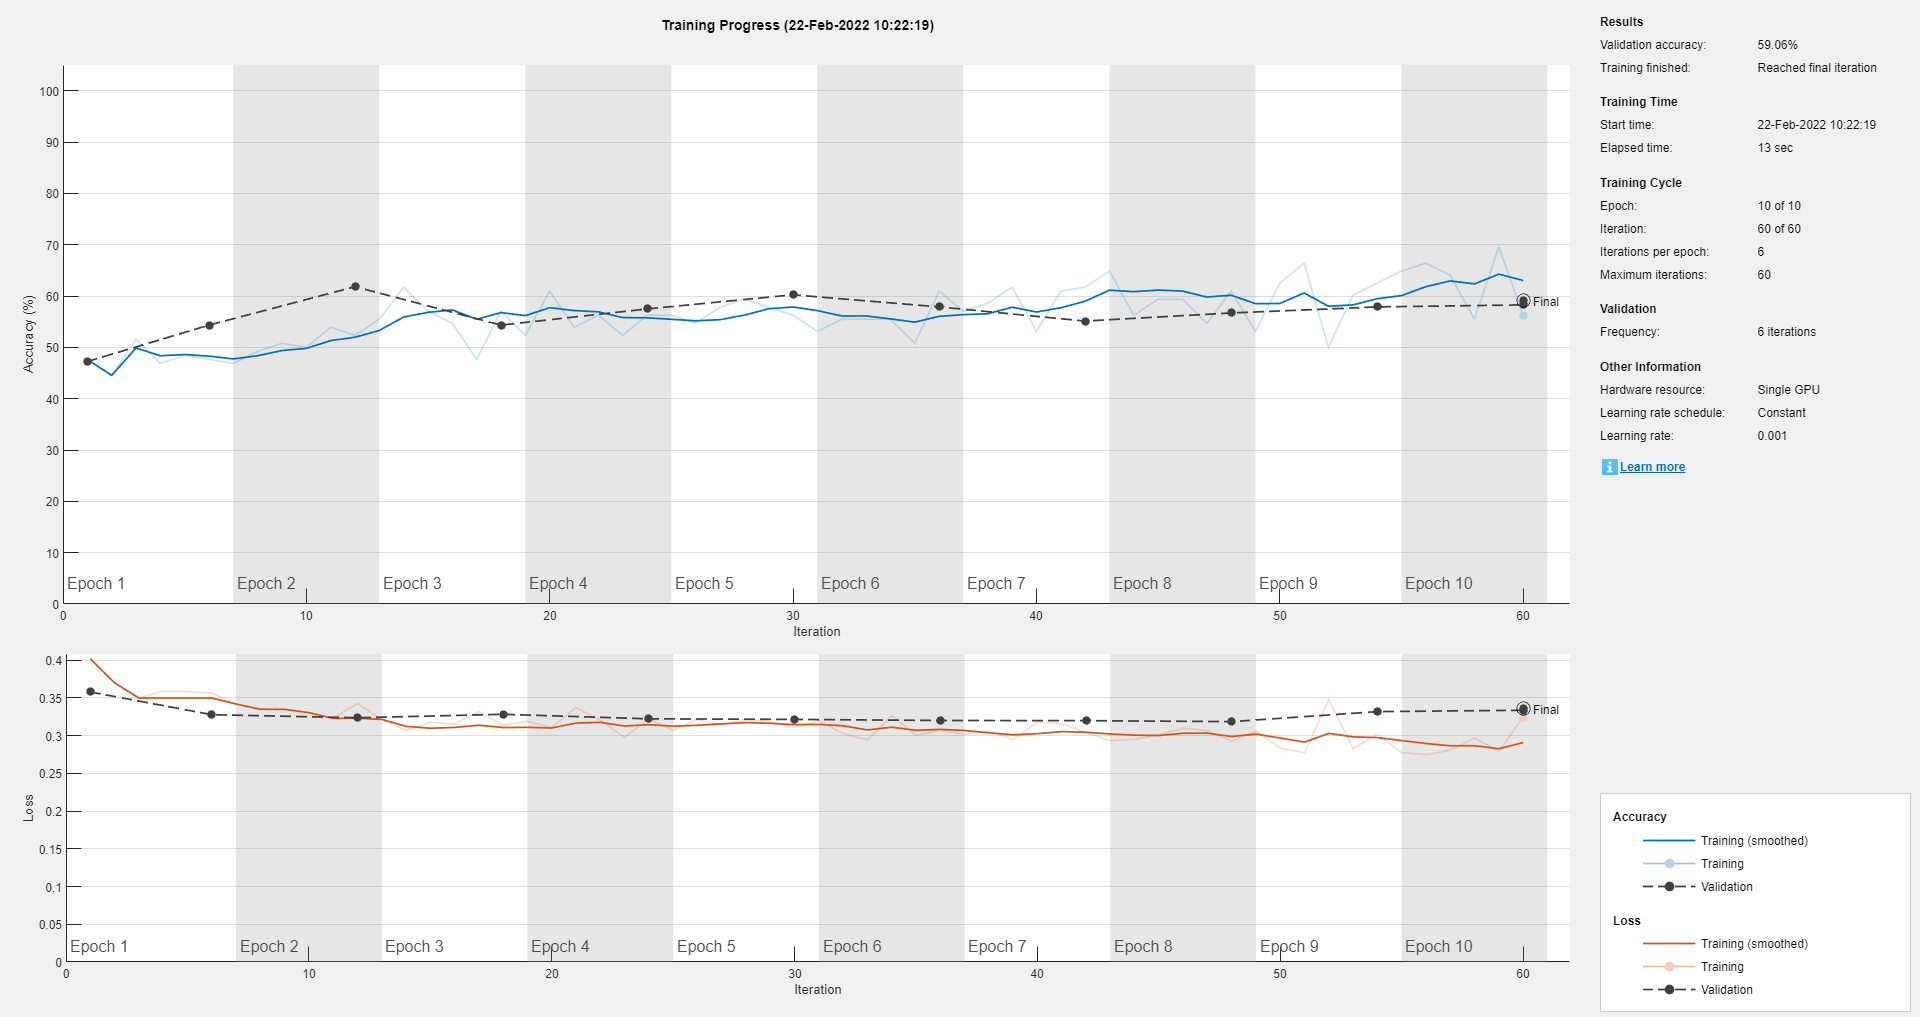

net_lstm = trainNetwork(FeaturesTrain, trueLabelsTrain, lgraph.Layers, options);

% net_lstm = trainNetwork(FeaturesTrain, trueLabelsTrain, layers, options);
% analyzeNetwork(net_lstm);

Classify the test data. Specify the same mini-batch size used for training.

predLabelsTrain = classify(net_lstm, FeaturesTrain, 'MiniBatchSize', miniBatchSize);
predLabelsVal = classify(net_lstm, FeaturesVal, 'MiniBatchSize', miniBatchSize);
predLabelsTest = classify(net_lstm, FeaturesTest, 'MiniBatchSize', miniBatchSize);

Calculate the classification accuracy of the predictions.

% acc = sum(predLabelsTest == trueLabelsTest)./numel(trueLabelsTest)
disp_results(predLabelsTrain, trueLabelsTrain);

acc       sensitivity     PPV     specificity
   60.9000    4.4000   77.8000   99.1000



disp_results(predLabelsVal, trueLabelsVal);

acc       sensitivity     PPV     specificity
   52.8000    0.9000   16.7000   96.4000



disp_results(predLabelsTest, trueLabelsTest);

acc       sensitivity     PPV     specificity
   63.4000    4.8000   83.3000   99.4000

